# MOTION CAPTURE LIVE SCRIPT

Connect and sort UART ports:

availablePorts = serialportlist;
searchSubstring = '/dev/tty.usbserial';
filteredPorts = availablePorts(contains(availablePorts, searchSubstring));
serialPorts = cell(1, 6);
camIDs = zeros(1,length(filteredPorts));
for i = 1:6
    serialPorts{i} = 0;
end

for i = 1:length(filteredPorts)
    serialPorts{i} = serialport(filteredPorts{i}, 115200); % Adjust COM port accordingly
    serialPorts{i}.writeline('INT');
    dataID = serialPorts{i}.readline()
    camIDs(i) = extractAfter(dataID,'0');
    serialPorts{i} = 0;
end

dataID = "03"

dataID = "02"

dataID = "04"

dataID = "05"

dataID = "01"


%Sort serial ports and get intriniscs:
sortedSerialPorts = cell(1,length(filteredPorts));
k=0;
for i = camIDs
    k = k+1;
    sortedSerialPorts{i} = filteredPorts{k};
    serialPorts{i} = serialport(filteredPorts{k}, 115200);       
end

activePorts = zeros(1,length(filteredPorts));
i=0;
for k = 1:length(serialPorts)
    if serialPorts{k} ~= 0
        i = i+1;
        activePorts(i) = k;
    end
end

%Intrinsic Calibration
cInt_VGA = cell(1,6);
cInt_QVGA = cell(1,6);
for k = 1:6
    filepath_VGA = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(k),'/CAM',num2str(k),'Params_GRAYSCALE.mat'];
    filepath_QVGA = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(k),'/CAM',num2str(k),'Params_RGB.mat'];
    file_VGA  = load(filepath_VGA);
    file_QVGA = load(filepath_QVGA);
    cInt_VGA{k} = file_VGA.cameraParams;
    cInt_QVGA{k} = file_QVGA.cameraParams;
end

uSkip = input('Would you like to skip calibration?(Y/N)\n','s');

uSkip = 'n'

if upper(uSkip) == 'Y'
    for i = 1:length(activePorts)
        serialPorts{i}.writeline('SKIP');
    end
end

%Extrinisc image point capture:
imagePoints_GRAY_norm = cell(1, 6);
imagePoints_GRAY_D = cell(1, 6);
bGO = true;
cameraCalibrationSuccess_GRAY = true(1,6);
cameraCalibrationSuccess_GRAY(activePorts) = false;
kMaxAttempts = 2; % Define the maximum number of attempts
j=0;
while any(~cameraCalibrationSuccess_GRAY) && (bGO) 
    j = j + 1;
    userAnswer = input('Would you like to attempt calibration? (Y/N)\n', 's');
    if upper(userAnswer) == 'Y'
        bGO = true;
    else
        bGO = false;
        activePorts = find(cameraCalibrationSuccess_GRAY);
        inactivePorts = find(~cameraCalibrationSuccess_GRAY);
        disp('CAMERAS:')
        disp(inactivePorts)
        disp('SET TO INACTIVE')
        break;
    end
    disp(['Calibration attempt ',num2str(j)])
    failedCAMS = find(~cameraCalibrationSuccess_GRAY);
    if length(failedCAMS) == length(serialPorts)
        disp('Attempting for all cams.')
    else
        failedCamerasStrArray = string(failedCAMS);
        disp('Attempt for cams:')
        disp(failedCamerasStrArray)
    end
    for i = activePorts
        % Close and open serial port to flush data
        if cameraCalibrationSuccess_GRAY(i)
            continue
        end
        serialPorts{i} = 0;
        % Pause
        pause(1);
        
        serialPorts{i} = serialport(sortedSerialPorts{i}, 115200);
        % Pause
        pause(1);
    
    
        bAttempting = true;
        k = 0; % Initialize attempt counter
    
        while bAttempting && k <= kMaxAttempts
            k = k + 1; % Increment attempt counter
            % Send command
            totalCap = 100;
            extDataTotal = zeros(5,2);
            for j = 1:totalCap
                serialPorts{i}.writeline('EXT_GRAY');
                data_str = serialPorts{i}.readline();
                
                try
                    extData = str2double(split(data_str{1}(1:end-1), ','));
                    if numel(extData) ~= 10 % Check if the data length is as expected
                        error('Data length mismatch');
                    end
                    % Reshape and normalize data
                    extData = reshape(extData, [2, 5])';
                    extDataTotal = extDataTotal+extData;
                catch err
                    fprintf('\rError for CAM %d, attempt %d: %s                     ', i, k, err.message);
                    fprintf('\rData: %s                                             \n', data_str);
                    pause(1);
                    totalCap = totalCap -1;
                end
            end
            extData = extDataTotal/totalCap
            try 
                imagePoints_GRAY_D{i} = extData;
                bAttempting = false; % Stop attempting after success
                serialPorts{i}.writeline('EXT_GRAY_SUCCESS');
                disp(['CAM ', num2str(i),' SUCCESSFUL.'])
                cameraCalibrationSuccess_GRAY(i) = true;
            catch err
                fprintf('\rError for CAM %d, attempt %d: %s                     ', i, k, err.message);
                fprintf('\rData: %s                                             \n', data_str);
                pause(1); 
            end
        end
        
        if k > kMaxAttempts
            disp(['Max attempts reached for CAM ', num2str(i)]);
        end
    end
end

Calibration attempt 1


Attempt for cams:


    "1"    "2"    "3"    "4"    "5"




Error for CAM 1, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 215,292,236,298,132,335,271,354,226,379,182,404,                                             



Error for CAM 1, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 215,292,236,298,132,335,271,354,226,379,182,404,                                             



Error for CAM 1, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 215,292,236,298,132,335,271,354,226,379,182,404,                                             



Error for CAM 1, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 215,292,235,297,132,335,271,354,226,379,182,404,                                             



Error for CAM 1, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 215,292,235,297,132,335,271,354,226,379,182,404,                                             



Error for CAM 1, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 215,292,235,297,132,335,271,354,226,379,182,404,                                             



Error for CAM 1, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 215,292,233,297,132,335,271,354,226,379,181,404,                                             



Error for CAM 1, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 474,1,215,292,132,335,271,354,226,379,182,404,                                             


extData =   215.0109  292.0000
  132.0000  335.0000
  271.0000  354.0000
  226.0000  379.0000
  181.7826  404.0000


CAM 1 SUCCESSFUL.



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,249,430,233,463,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,250,430,234,463,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,250,429,252,442,234,463,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,250,429,234,463,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,250,430,234,463,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,250,430,252,440,234,463,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,251,424,249,431,234,463,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,250,429,234,464,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,250,430,234,464,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,249,430,234,463,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,250,430,234,463,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,249,430,234,463,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,249,430,234,463,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,249,430,234,463,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,249,431,234,463,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,249,431,234,464,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,249,431,234,463,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             



Error for CAM 2, attempt 1: Index exceeds the number of array elements. Index must not exceed 3.                     


Data: 263,226,232,246,200,267,265,312,                                             


disp('Pausing for 5 seconds for tracking algorithm...')
pause(5)


%Extrinsics data calc:

%SET WORLD POINTS:
F1_B = [-0.12 0.12]; %RED
F2_B = [0.12 -0.12]; %GREEN
F3_B = [0.12 0.12]; %BLUE
F4_B = [-0.12 -0.12]; %PURPLE
F5_B = [-0.12 0]; %WHITE
worldPoints = [F1_B;F2_B;F3_B;F4_B;F5_B];

IP_GRAY_UNDIST_UNSORT = cell(1, length(serialPorts));
for i = activePorts
    IP_GRAY_UNDIST_UNSORT{i} = undistortPoints(imagePoints_GRAY_D{i},cInt_VGA{i}.Intrinsics);
end
extrinsics_RGB = cell(1, length(serialPorts));
extrinsics = cell(1, length(serialPorts));
camPose = cell(1, length(serialPorts));
calibPoints = cell(1, length(serialPorts));

% Running sorting algorithm for extrinsics calibration
IP_GRAY_UNDISTORED = cell(1,length(serialPorts));
for i = activePorts
    disp(['CAM ',num2str(i),':'])
    point_indicies = 1:5;
    all_permutations = perms(point_indicies);
    min_error = inf;
    best_fit = [];
    for k = 1:length(all_permutations)
        k;
        current_permutation = all_permutations(k, :);
        imagePoints_GRAY = IP_GRAY_UNDIST_UNSORT{i}(current_permutation,:);
        extrinsicsEstimate = estimateExtrinsics(imagePoints_GRAY,worldPoints,cInt_VGA{i}.Intrinsics);
        BP_UV = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsicsEstimate.A), cInt_VGA{i}.Intrinsics);
        ReprojectionErrors = BP_UV - imagePoints_GRAY;
        squareErrors = ReprojectionErrors.^2;
        mean_squareError = mean(squareErrors,'all');
        rmse = sqrt(mean_squareError);
        if rmse < min_error
            camPose_possible  = extr2pose(extrinsicsEstimate);
            if (camPose_possible.Translation(3) > 0) %Geometric constraint, cameras are above world zero point(the floor)
                min_error = rmse;
                best_fit = current_permutation;
            else
                continue
            end
        end
    end
    IP_GRAY_UNDISTORED{i} = IP_GRAY_UNDIST_UNSORT{i}(best_fit,:);
    extrinsics{i} = estimateExtrinsics(IP_GRAY_UNDISTORED{i},worldPoints,cInt_VGA{i}.Intrinsics);
    camPose{i}  = extr2pose(extrinsics{i});
end

CAM 1:
CAM 2:
CAM 3:
CAM 4:
CAM 5:



for i = activePorts
    disp(['CAM ', num2str(i),':'])
    camPose{i}
end

CAM 1:


ans =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.8762 0.3409 1.0616]
                 R: [3×3 double]
                 A: [4×4 double]


CAM 2:


ans =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [1.0627 -1.1551 0.9543]
                 R: [3×3 double]
                 A: [4×4 double]


CAM 3:


ans =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.2942 0.3092 1.3353]
                 R: [3×3 double]
                 A: [4×4 double]


CAM 4:


ans =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-1.3600 -1.2669 1.2258]
                 R: [3×3 double]
                 A: [4×4 double]


CAM 5:


ans =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [1.1897 -0.1591 1.1766]
                 R: [3×3 double]
                 A: [4×4 double]


% BACK PROJECTION CHECK:
rootmeanerrors = zeros(1,6);
for i = activePorts
    disp(['CAM ',num2str(i), ' REPROJECTION ERRORS [RED;BLUE;GREEN;MAGENTA;WHITE]'])
    BP_UV = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics{i}.A), cInt_VGA{i}.Intrinsics);
    DIFF = abs(IP_GRAY_UNDISTORED{i} - BP_UV);
    disp('Reprojection Errors:')
    disp(DIFF)
    squareErrors = DIFF.^2;
    mean_SquareError = mean(squareErrors,'all');
    rmse = sqrt(mean_SquareError);
    disp('Root mean square errors:')
    disp(rmse)
    rootmeanerrors(i) = rmse;
end

CAM 1 REPROJECTION ERRORS [RED;BLUE;GREEN;MAGENTA;WHITE]


Reprojection Errors:


    2.5380    0.2392
    1.6673    0.3420
    3.3022    1.0553
    2.9702    0.7489
    1.5247    0.5478



Root mean square errors:


    1.8282



CAM 2 REPROJECTION ERRORS [RED;BLUE;GREEN;MAGENTA;WHITE]


Reprojection Errors:


    0.7397    1.7141
    1.0430    2.2248
    2.0231    0.6450
    1.8685    0.5943
    1.7453    0.4374



Root mean square errors:


    1.4531



CAM 3 REPROJECTION ERRORS [RED;BLUE;GREEN;MAGENTA;WHITE]


Reprojection Errors:


    0.9805    0.5798
    0.8511    0.5727
    0.1280    2.4937
    0.5673    1.9951
    0.0770    0.8621



Root mean square errors:


    1.1677



CAM 4 REPROJECTION ERRORS [RED;BLUE;GREEN;MAGENTA;WHITE]


Reprojection Errors:


    2.0824    0.2655
    2.0729    0.3480
    1.8377    0.3065
    2.0446    0.5070
    0.1001    0.2313



Root mean square errors:


    1.2960



CAM 5 REPROJECTION ERRORS [RED;BLUE;GREEN;MAGENTA;WHITE]


Reprojection Errors:


    6.1729    0.6423
    7.0004    0.8350
    0.8390    3.4431
    0.5980    2.7438
    3.2614    1.1858



Root mean square errors:


    3.4743




% minRepError = 1;
% IgnoreInput = input(['Would you like to ignore cameras with Reprojection Error > ', num2str(minRepError),'?(Y/N)\n'],'s');
% ErrorCheck = false(1,6);
% if upper(IgnoreInput) == 'Y'
%     for i=activePorts
%         if rootmeanerrors(i) < minRepError
%             ErrorCheck(i) = true;
%         end
%     end
%     activePorts = find(ErrorCheck);
%     disp('Cameras:')
%     disp(activePorts)
%     disp('only set to active')
% end

%OPTIONAL - Optimize Extrinsics Calibration:
optimizedExt = cell(1, length(serialPorts));
optimizedCamPose = cell(1, length(serialPorts));

for i = activePorts
    % Load Intrinsic Camera Parameters
    cameraParams = cInt_VGA{i}; 

    % Define 3D World Points
    worldPoints_XYZ = [worldPoints, zeros(5,1)]; 

    % Define Corresponding 2D Image Points
    imagePoints = IP_GRAY_UNDISTORED{i};

    % Residual Function for Reprojection Error
    residualFunc = @(pose) computeReprojectionError(pose, worldPoints_XYZ, imagePoints, cameraParams);

    % Initial Guess for Pose Parameters
    eulAng = rotm2eul(extrinsics{i}.R);
    initialPose = [eulAng, extrinsics{i}.Translation]; 

    % Nonlinear Least Squares Optimization
    options = optimoptions('lsqnonlin', 'Display', 'iter');
    optimizedPose_VAL = lsqnonlin(residualFunc, initialPose, [], [], options);
    
    % Update Optimized Extrinsic Parameters
    optimizedExt{i} = extrinsics{i};
    optimizedExt{i}.R = eul2rotm(optimizedPose_VAL(1:3));
    optimizedExt{i}.Translation = optimizedPose_VAL(4:6);
    optimizedExt{i}.A = [optimizedExt{i}.R, optimizedExt{i}.Translation'; 0, 0, 0, 1];
    optimizedCamPose{i} = extr2pose(optimizedExt{i});
end 


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          7           33.4216                              464
     1         14           1.55073       0.0906579             44.4      
     2         21           1.44438       0.0060815            0.426      
     3         28           1.44438     3.17513e-05         0.000325      
     4         35           1.44438     9.98995e-08         1.78e-06      

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteri


for i = activePorts
    disp(['CAM ', num2str(i),':'])
    optimizedCamPose{i}
end

CAM 1:


ans =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.8467 0.3457 1.1738]
                 R: [3×3 double]
                 A: [4×4 double]


CAM 2:


ans =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [1.0815 -1.1233 1.0894]
                 R: [3×3 double]
                 A: [4×4 double]


CAM 3:


ans =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.3426 0.4351 1.2760]
                 R: [3×3 double]
                 A: [4×4 double]


CAM 4:


ans =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-1.3850 -1.1480 1.1680]
                 R: [3×3 double]
                 A: [4×4 double]


CAM 5:


ans =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [1.1930 0.1078 1.0753]
                 R: [3×3 double]
                 A: [4×4 double]



optimized_rootmeanerrors = zeros(1,6);

%BACK PROJECTION CHECK:
for i = activePorts
    disp(['CAM ',num2str(i), ' REPROJECTION ERRORS [RED;BLUE;GREEN;MAGENTA;WHITE'])
    BP_UV = world2img([worldPoints zeros(5,1)], rigidtform3d(optimizedExt{i}.A), cInt_VGA{i}.Intrinsics);
    DIFF = abs(IP_GRAY_UNDISTORED{i} - BP_UV);
    disp(DIFF)
    squareErrors = DIFF.^2;
    mean_SquareError = mean(squareErrors,'all');
    rmse = sqrt(mean_SquareError);
    disp('Root mean square errors:')
    disp(rmse)
    optimized_rootmeanerrors(i) = rmse;
end

CAM 1 REPROJECTION ERRORS [RED;BLUE;GREEN;MAGENTA;WHITE


    0.2427    0.2742
    0.2277    0.3455
    0.1877    0.3918
    0.5131    0.3798
    0.7215    0.1491



Root mean square errors:


    0.3800



CAM 2 REPROJECTION ERRORS [RED;BLUE;GREEN;MAGENTA;WHITE


    0.1167    0.1410
    0.0540    0.1812
    0.0889    0.1962
    0.2495    0.2121
    0.4028    0.0846



Root mean square errors:


    0.1981



CAM 3 REPROJECTION ERRORS [RED;BLUE;GREEN;MAGENTA;WHITE


    0.0549    0.2053
    0.5397    0.4645
    0.2976    0.5161
    0.6258    0.4546
    0.3263    0.3188



Root mean square errors:


    0.4139



CAM 4 REPROJECTION ERRORS [RED;BLUE;GREEN;MAGENTA;WHITE


    0.0914    0.0883
    0.1525    0.0198
    0.1647    0.0337
    0.1659    0.1385
    0.0854    0.2400



Root mean square errors:


    0.1340



CAM 5 REPROJECTION ERRORS [RED;BLUE;GREEN;MAGENTA;WHITE


    0.0660    0.5098
    0.0421    0.5790
    0.0356    0.5986
    0.1774    0.6656
    0.3273    0.1813



Root mean square errors:


    0.3969





disp("Initializing fundamental matrices...")

Initializing fundamental matrices...


F = cell(6,6);
for i = activePorts
    for k = activePorts
        if i ~= k
            %F{i,k} = Line drawn from CAM i onto CAM k frame.
            F{i,k} = FMat(cInt_VGA{i},cInt_VGA{k},camPose{i},camPose{k});
        end
    end
end
pause(1)

disp("Initializing feature position with respect to body frame...")

Initializing feature position with respect to body frame...


pause(1)
%CHANGE IF NOT TRACKING CALIBRATION PLATFORM
f2b_1 = [F1_B'; 0];
f2b_2 = [F2_B'; 0];
f2b_3 = [F3_B'; 0];

disp("Intializing C matrices...")

Intializing C matrices...


pause(1)
C = cell(1,6);
opt_C = cell(1,6);
unopt_C = cell(1,6);
for i = activePorts
    T = camPose{i}.A;
    invT = T\eye(4);
    K = [cInt_VGA{i}.K zeros(3,1)];
    C_temp = K*invT;         
    C_temp = C_temp/C_temp(3,4);    %NORMALIZING C MATRICES
    unopt_C{i} = C_temp;
    
    %Optimized ext:
    optimizedT = optimizedCamPose{i}.A;
    invoptimzedT = optimizedT\eye(4);
    C_tempOpt = K*invoptimzedT;
    C_tempOpt = C_tempOpt/C_tempOpt(3,4); 
    opt_C{i} = C_tempOpt;
end
optInput = input('Would you like to use optimized C matrices?(Y/N)\n','s');
if upper(optInput) == 'Y' 
    for i = activePorts
        C{i} = opt_C{i};
    end
else
    for i = activePorts
        C{i} = unopt_C{i};
    end
end

disp('Initializing state variables...')

Initializing state variables...


%Set to initial position and orientation to [0;0;0] and qI if calibration
%was done in. If not, triangulate initial position and orientation based on
%sensor readings. - still need to add code for this
stateVarInput = input('Have you ran the EKF code using these extrinsics?(Y/N)\n','s');
if stateVarInput == 'Y'
    P = [GraphXk{1}(k);GraphXk{2}(k);GraphXk{3}(k)];
    V = [0;0;0]; 
    q = [GraphXk{7}(k);GraphXk{8}(k);GraphXk{9}(k);GraphXk{10}(k)];
    omega = [0;0;0];
else
    P = [0;0;0]; % Initial [X;Y;Z] of tracked robot
    V = [0;0;0]; % Initial [Vx;Vy;Vz] of tracked robot
    q = [1;0;0;0]; %Initial [q0;qx;qy;qz] of tracked robot
    omega = [0;0;0]; %Inital [omega_x;omega_y;omega_z] of tracked robot
end
Xk = [P;V;q;omega];

disp('Initializing process covariance matrix...')

Initializing process covariance matrix...


%Set error in position, velocity, orientation and angular velocity
eP = ones(1,3) * 0.1;
eV = ones(1,3) * 0.00001;
eQuat = ones(1,4) * 0.1;
eOmega = ones(1,3) * 0.0001;
% Create a vector containing the diagonal elements of Pk
diagonalElements = [eP, eV, eQuat, eOmega];
% Initializing Pk:
Pk = diag(diagonalElements);

disp('Initializing Q and R...')

Initializing Q and R...


%Adjust Q and R values to put more trust in either model. If Q<<R it puts
%more trust in the system state model, if R>>Q it puts more trust in the
%observation model.
Amax = 0.5; %Adjust Q here, maximum acceleration
eA = sqrt((Amax-(-Amax))^2/12)/2*ones(1,3);  
alpha_max = 0.01; %Adjust Q here, maximum angular acceleration
ealpha = sqrt((alpha_max-(-alpha_max))^2/12)*ones(1,3); 
Q = diag([eA,ealpha]);

%As R will change in size depending on how many cameras send information at
%a certain timestamp, we can only initialize the value that will go along 
%the diagnonal.
R_r = 1/(12); %Adjust R matrix here

%Initialize max size of HXkp matrix cell to keep track of HXkp through
%previous iterations
HXkp_32 = cell(1,6);
HXkp = cell(1,6);
H_6x13 = cell(1,6);
for i = 1:6
    HXkp_32{i} = [];
    HXkp{i} = [];
    H_6x13{i} = [];
end


% bAccept = false;
% while ~bAccept
%     RunTime = input('How many seconds would you like to run the EKF for?\n','s');
%     try 
%         RunTime = str2double(RunTime);
%         bAccept = true;
%     catch err
%         disp('Please enter integer value.')
%         disp(err)
%     end
% end

% Pre-allocate size of data arrays for graphing: 
% Not sure how many iterations there will be, in simulation there was about 
% ±1 mill for 25s, assuming the cameras are sending data every 0.025s.

GraphXk = cell(16,1);
%GraphXk{1:13} = Xk values.
%GraphXk{14:15} = Total run time at iteration k, refresh rate (hz) at iteration k.
allocatedSpace = 100000; %allocating 10 mill spaces
for i = 1:length(GraphXk)
    GraphXk{i} = NaN(allocatedSpace,1);
end
GraphXk{16} = NaT(allocatedSpace,1,'Format','HH:mm:ss.SSS');
bDATA_Check = cell(10000,1);

%Initiliazing data sort array:
cam_data = cell(1,6);
cam_data32 = cell(1,6);
prev_UV = cell(1,6);
UV = cell(1,6);
%If calibration occured, set initial UV to old UV
for i = activePorts
    prev_UV{i} = IP_GRAY_UNDISTORED{i}(1:3,:);
end

%Set stop time in seconds: 
StopTime = 60;

%Set buffer time in seconds:
bufferTime = 0.001;


%Initializing iteration counter:
k = 0;
c = 0;
l = 0;
iter_k = 0;
test_time_data = zeros(100000,1);
numBytesPerIter = zeros(6,100000);

%Sending starts to serial ports:
%close ports, then open them to flush data
for i = activePorts
    serialPorts{i} = 0; 
end

disp('Opening ports...')

Opening ports...


pause(1) %pausing for 1 second to ensure activation
for i = activePorts
    serialPorts{i} = serialport(sortedSerialPorts{i},115200);
    flush(serialPorts{i});
end

disp('Starting camera tracking... waiting 10s to start moving rod')

Starting camera tracking... waiting 10s to start moving rod


pause(10) %pausing for 1 seconds to ensure sending bits.

%Setting EKF elapse time to 0:
EKFTotalTime = 0;
% initializing clock:
lastUpdateTime = tic;
for i = activePorts
    serialPorts{i}.writeline('START'); 
end
% Initialize clock or start recieivng data from serial ports first?
try
    while (EKFTotalTime<StopTime)
        %Allocating more space if needed:
        if k >= allocatedSpace
            for i = 1:15
                GraphXk{i} = [GraphXk{i}; NaN(allocatedSpace, 1)]; % Double the size
                allocatedSpace = size(GraphXk{i});
            end
        end
    
        %EKF code that needs to be run in open and closed loop:
        k = k+1;
        dT = toc(lastUpdateTime);
        GraphXk{15}(k) = 1/dT;
        EKFTotalTime = EKFTotalTime + dT;
        GraphXk{14}(k) = EKFTotalTime;
        lastUpdateTime = tic;
        A = [1, 0, 0, dT, 0, 0, 0, 0, 0, 0, 0, 0, 0; 
             0, 1, 0, 0, dT, 0, 0, 0, 0, 0, 0, 0, 0; 
             0, 0, 1, 0, 0, dT, 0, 0, 0, 0, 0, 0, 0; 
             0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0; 
             0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0; 
             0, 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0; 
             0, 0, 0, 0, 0, 0, 1, 0, 0, 0, -(dT*Xk(8))/2, -(dT*Xk(9))/2, -(dT*Xk(10))/2; 
             0, 0, 0, 0, 0, 0, 0, 1, 0, 0, (dT*Xk(7))/2, -(dT*Xk(10))/2, (dT*Xk(9))/2; 
             0, 0, 0, 0, 0, 0, 0, 0, 1, 0, (dT*Xk(10))/2, (dT*Xk(7))/2, -(dT*Xk(8))/2; 
             0, 0, 0, 0, 0, 0, 0, 0, 0, 1, -(dT*Xk(9))/2, (dT*Xk(8))/2, (dT*Xk(7))/2; 
             0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0; 
             0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0; 
             0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1];
        Xkp = A*Xk;
        G = [0 0 0 0 0 0;
            0 0 0 0 0 0;
            0 0 0 0 0 0;
            dT 0 0 0 0 0;
            0 dT 0 0 0 0;
            0 0 dT 0 0 0;
            0 0 0 0 0 0;
            0 0 0 0 0 0;
            0 0 0 0 0 0;
            0 0 0 0 0 0;
            0 0 0 dT 0 0;
            0 0 0 0 dT 0;
            0 0 0 0 0 dT];
        Qk = G*Q*G';
        Pkp = A*Pk*A' + Qk;
    
         %Checking if there's any data from serialports:
        bData = false(1,6);
        
        %If there is data, pause for a buffer time and then check all ports
        %for more data
        for i = activePorts
            bData(i) = (serialPorts{i}.NumBytesAvailable > 0);
            numBytesPerIter(i,k) = serialPorts{i}.NumBytesAvailable;
        end

        bDATA_Check{k} = bData;
        %Choosing to run in open loop or in closed loop:
        if any(bData)
            l = l+1;
            %Consider data to be synchronized if their timestamps are within
            %200hz of eachother (which is the lower quater percentile value of
            %the EKF code refresh rate in simulation). If data are outside of
            %4ms of one another, consider them to be not in sync. 
            %OR
            %Run code on data that has been recieved this instant. There might
            %be a case where the data will be recieved constantly, but that is
            %not a big deal as the EKF will update using the observations
            %constantly, downside is that the EKF Update rate might take too 
            %long as the EKF operates at a ±250Hz refresh rate, and if cameras
            %send data <1ms between eachother it will effectivly slow down this
            %process as the data will be read and processed individually;
    

            %Getting data from camera, verifying the data is usable and
            %processing the (unsorted) data into a 3x2 matrix
            
            for i = find(bData)
                %Reading camera data for camera 1    
                try
                    data = serialPorts{i}.readline();
                    [timestamp,data] = parseData(data);          
                    cam_data32_dist = reshape(data,[2 3])';
                    cam_data32{i} = undistortPoints(cam_data32_dist,cInt_VGA{i}.Intrinsics);
                catch
                    bData(i) = false;
                end
            end
            
            if sum(bData) == 0
                %OPEN LOOP CODE:
                q = Xkp(7:10)';
                qnorm = q/norm(q);
                Xkp(7:10) = qnorm';
                Xk = Xkp;
                Pk = Pkp;
                %GRAPHING SAVE:
                for i = 1:13        
                    GraphXk{i}(k) = Xk(i);
                end
                %SAVING TIMESTAMP:
                currentTime = datetime('now', 'Format', 'HH:mm:ss.SSS');
                GraphXk{16}(k) = currentTime;
                continue;
            end

            quat = [Xkp(7) Xkp(8) Xkp(9) Xkp(10)];
            normquat = quat/norm(quat);
            R_quat = quat2rotm(normquat);

            % STEP 3:
            for i = activePorts
                H_6x13{i} = HCreate(C{i},Xkp,bData(i),f2b_1,f2b_2,f2b_3);
                [HXkp{i},HXkp_32{i}] = createHXkp(Xkp,R_quat,f2b_1,f2b_2,f2b_3,extrinsics{i},cInt_VGA{i}.Intrinsics,bData(i));
                prev_UV{i} = HXkp_32{i};
            end

            for i = find(bData)
                UV{i} = UV_prevSORT(cam_data32{i},prev_UV{i},bData(i));
                % H_6x13{i} = HCreate(C{i},Xkp,bData(i),f2b_1,f2b_2,f2b_3);
            end

            
            H = [H_6x13{1};H_6x13{2};H_6x13{3};H_6x13{4};H_6x13{5};H_6x13{6}];


            R = R_r*createR(sum(bData));

            KG = (Pkp*H')/(H*Pkp*H'+ R);

            %STEP 4:
            Yk = createYk(UV{1},UV{2},UV{3},UV{4},UV{5},UV{6},bData(1),bData(2),bData(3),bData(4),bData(5),bData(6));

            %STEP 5                       
            HXkp_mat = [HXkp{1};HXkp{2};HXkp{3};HXkp{4};HXkp{5};HXkp{6}];

            %UPDATE Xk
            Xk = Xkp + KG*(Yk - HXkp_mat);
            
            quat = [Xk(7) Xk(8) Xk(9) Xk(10)];
            normquat = quat/norm(quat);
            Xk(7) = normquat(1);
            Xk(8) = normquat(2);
            Xk(9) = normquat(3);
            Xk(10) = normquat(4);

            % Update state Xk and covariance Pk with observations
            Pk = (eye(13) - KG*H)*Pkp;
            
        else
            %OPEN LOOP CODE:
            q = Xkp(7:10)';
            qnorm = q/norm(q);
            Xkp(7:10) = qnorm';
            Xk = Xkp;
            Pk = Pkp;
        end
        
        %GRAPHING SAVE:
        for i = 1:13        
            GraphXk{i}(k) = Xk(i);
        end
        %SAVING TIMESTAMP:
        currentTime = datetime('now', 'Format', 'HH:mm:ss.SSS');
        GraphXk{16}(k) = currentTime;
    end

    disp('Ending camera tracking...')
    %ENDING Camera data capture task:
    for i = activePorts
        serialPorts{i}.writeline('END'); 
        flush(serialPorts{i});
    end
    
    disp('Closing ports...')
    %Closing serial ports
    for i = activePorts
        serialPorts{i} = 0; 
    end

catch ME
    disp(getReport(ME, 'extended', 'hyperlinks', 'off'))
    for i = activePorts        
        serialPorts{i}.writeline('END'); 
        serialPorts{i} = 0;
    end
end

Ending camera tracking...


Closing ports...


for i = activePorts
    serialPorts{i}.writeline('END'); 
    flush(serialPorts{i});
end

%SAVE DATA SECTION:

%Cut off unused storage
for i = 1:length(GraphXk)
    GraphXk{i}=GraphXk{i}(1:k);
end

% Convert Data into an Array
data = zeros(k,length(GraphXk));
for idx = 1:(length(GraphXk)-1)
    data(:,idx) = GraphXk{idx};
end
% Apply headings to maintain structure
headings = {'X_Pos', 'Y_Pos', 'Z_Pos', 'X_Vel', 'Y_Vel', 'Z_Vel', 'q0', 'qx', 'qy', 'qz', 'omega_x', 'omega_y', 'omega_z', 'EKFElapsedTime', 'RefreshRate','TimeStamps'};

% Create a table with array
T = array2table(data, 'VariableNames', headings);

% Now add the datetime column separately
T.TimeStamps = GraphXk{16}; % Add the datetime data to the end of the table

% Generate the current date and time string formatted as 'YYYYMMDD_HHMMSS'
dateTimeNow = datetime('now', 'Format', 'yyyy-MM-dd_HH-mm-ss');

% Create the filename with the date-time string
fileName = sprintf('EKFData_%s.csv', dateTimeNow);

% Specify the directory you want to save the file in
folderPath = '/Users/ferialmeyer/Documents/RESULTS/EKFData';  % Update this path

% Combine the folder path and filename to create a full file path
fullFilePath = fullfile(folderPath, fileName);

% Write the table to a CSV file at the specified location
writetable(T, fullFilePath);

% Inform the user
fprintf('Data saved to %s\n', fullFilePath);

Data saved to /Users/ferialmeyer/Documents/RESULTS/EKFData/EKFData_2024-04-03_10-20-34.csv



%SAVING CAMERA COUNT DATA (IN CASE)
i=0;
k;
pos_record = zeros(i,1);
for p = 1:k
    if any(bDATA_Check{p})
        i = i+1;
        pos_record(i) = p;
    end   
end


pos_record_2cams = zeros(k,1);
count1=0;
count2=0;
count3=0;
count4=0;
count5=0;
count6=0;
openLoopCount=0;
for p = 1:k
    switch sum(bDATA_Check{p})
        case 1
            count1=count1+1;
        case 2
            count2=count2+1;
        case 3
            count3=count3+1;
        case 4
            count4=count4+1;
        case 5
            count5=count5+1;
        case 6
            count6=count6+1;
        otherwise
            openLoopCount=openLoopCount+1;
    end
end

dataCount = [openLoopCount,count1,count2,count3,count4,count5,count6];
headingsCAM = {'openLoopCount','count1','count2','count3','count4','count5','count6'};

% Create a table with array
T = array2table(dataCount, 'VariableNames', headingsCAM);

% Generate the current date and time string formatted as 'YYYYMMDD_HHMMSS'
dateTimeNow = datetime('now', 'Format', 'yyyy-MM-dd_HH-mm-ss');

% Create the filename with the date-time string
fileName = sprintf('CameraCountData_%s.csv', dateTimeNow);

% Specify the directory you want to save the file in
folderPath = '/Users/ferialmeyer/Documents/RESULTS/CameraCountData';  % Update this path

% Combine the folder path and filename to create a full file path
fullFilePath = fullfile(folderPath, fileName);

% Write the table to a CSV file at the specified location
writetable(T, fullFilePath);

% Inform the user
fprintf('Data saved to %s\n', fullFilePath);

Data saved to /Users/ferialmeyer/Documents/RESULTS/CameraCountData/CameraCountData_2024-04-03_10-20-35.csv



%CAPTURE SPACE CALC:
CamDist = zeros(1,length(activePorts));

%Error checking (stationary)
error = abs([Xk(1);Xk(2);Xk(3)] - [0;0;0]);
error_3D = norm(error);

error_mean = abs([mean(GraphXk{1}(1:k));mean(GraphXk{2}(1:k));mean(GraphXk{3}(1:k))] - [0;0;0]);
error_3D_mean = norm(error_mean);

eulZYX = quat2eul([Xk(7) Xk(8) Xk(9) Xk(10)]);
error_eul = abs([rad2deg([0 0 0])] - rad2deg(eulZYX));
error_eul_3D = norm(error_eul);

eulZYX_mean = quat2eul([mean(GraphXk{7}(1:k)) mean(GraphXk{8}(1:k)) mean(GraphXk{9}(1:k)) mean(GraphXk{10}(1:k))]);
error_eul_mean = abs([rad2deg([0 0 0])] - rad2deg(eulZYX_mean));
error_eul_3D_mean = norm(error_eul_mean);

hz_average = k/EKFTotalTime;

for i = 1:length(activePorts)
    CamDist(i) = norm(optimizedCamPose{activePorts(i)}.Translation);
    disp(['CAM ',num2str(activePorts(i)),' distance away from [0;0;0] w.r.t {W}: ',num2str(CamDist(i)),'m'])
end

CAM 1 distance away from [0;0;0] w.r.t {W}: 1.4411m
CAM 2 distance away from [0;0;0] w.r.t {W}: 1.9378m
CAM 3 distance away from [0;0;0] w.r.t {W}: 1.3987m
CAM 4 distance away from [0;0;0] w.r.t {W}: 2.1046m
CAM 5 distance away from [0;0;0] w.r.t {W}: 1.6437m


disp(['Final position error of: ', num2str(error_3D),' meters'])

Final position error of: 0.28159 meters


disp(['Average position error of: ', num2str(error_3D_mean),' meters'])

Average position error of: NaN meters


disp(['Final orientation error of: ', num2str(error_eul_3D),' degrees'])

Final orientation error of: 33.4516 degrees


disp(['Average orientation error of: ', num2str(error_eul_3D_mean),' degrees'])

Average orientation error of: NaN degrees


disp(['Time taken to run simulation code: ', num2str(EKFTotalTime), ' seconds for ', num2str(k),' iterations'])

Time taken to run simulation code: 60.0017 seconds for 21850 iterations


disp(['Average refresh rate of code: ', num2str(hz_average), ' hz'])

Average refresh rate of code: 364.1561 hz


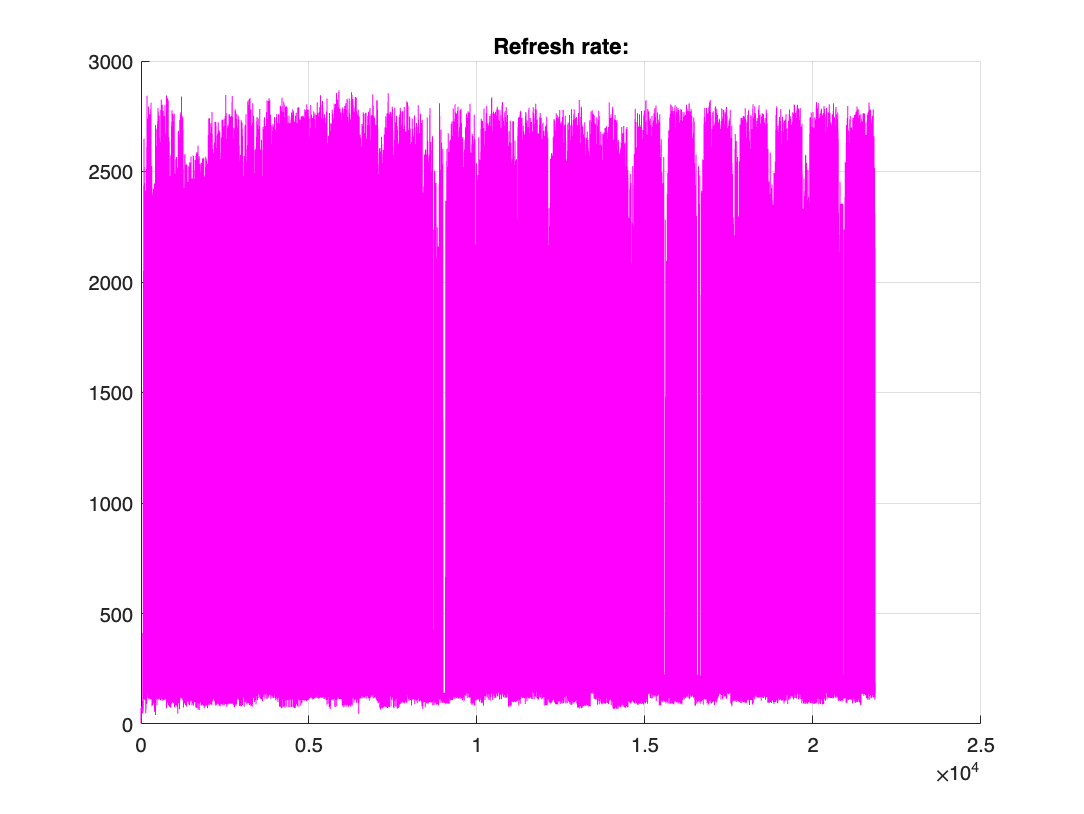


%GRAPHING HZ:
figure(1),clf,grid,hold on
title('Refresh rate:')
plot(linspace(1,k,k),GraphXk{15}(1:k),'m-')

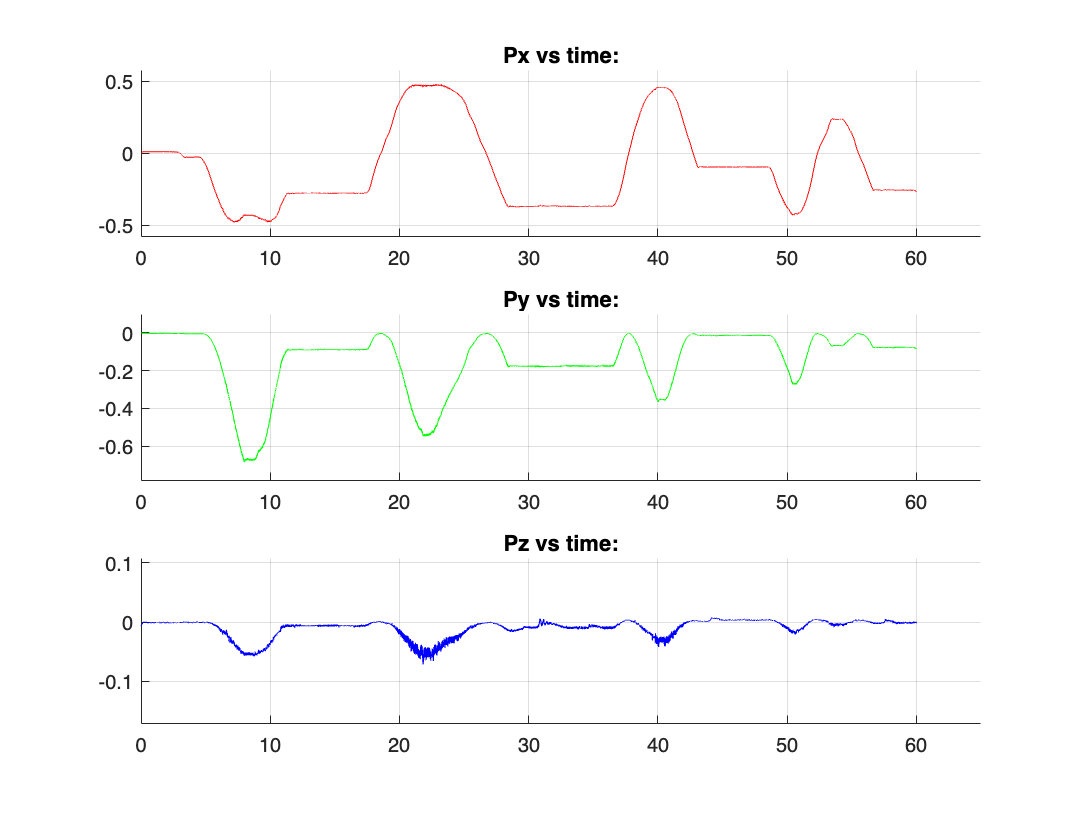


% Create a new figure
figure('Name', 'Position vs Time Plots'), clf

% Subplot for Xk's X position vs time
subplot(3, 1, 1), grid, hold on
title('Px vs time:')
plot(GraphXk{14}(1:k), GraphXk{1}(1:k), 'r-')
axis([0 GraphXk{14}(k)+5 min(GraphXk{1}(1:k))-0.1 max(GraphXk{1}(1:k))+0.1])

% Subplot for Xk's Y position vs time
subplot(3, 1, 2), grid, hold on
title('Py vs time:')
plot(GraphXk{14}(1:k), GraphXk{2}(1:k), 'g-')
axis([0 GraphXk{14}(k)+5 min(GraphXk{2}(1:k))-0.1 max(GraphXk{2}(1:k))+0.1])

% Subplot for Xk's Z position vs time
subplot(3, 1, 3), grid, hold on
title('Pz vs time:')
plot(GraphXk{14}(1:k), GraphXk{3}(1:k), 'b-')
axis([0 GraphXk{14}(k)+5 min(GraphXk{3}(1:k))-0.1 max(GraphXk{3}(1:k))+0.1])

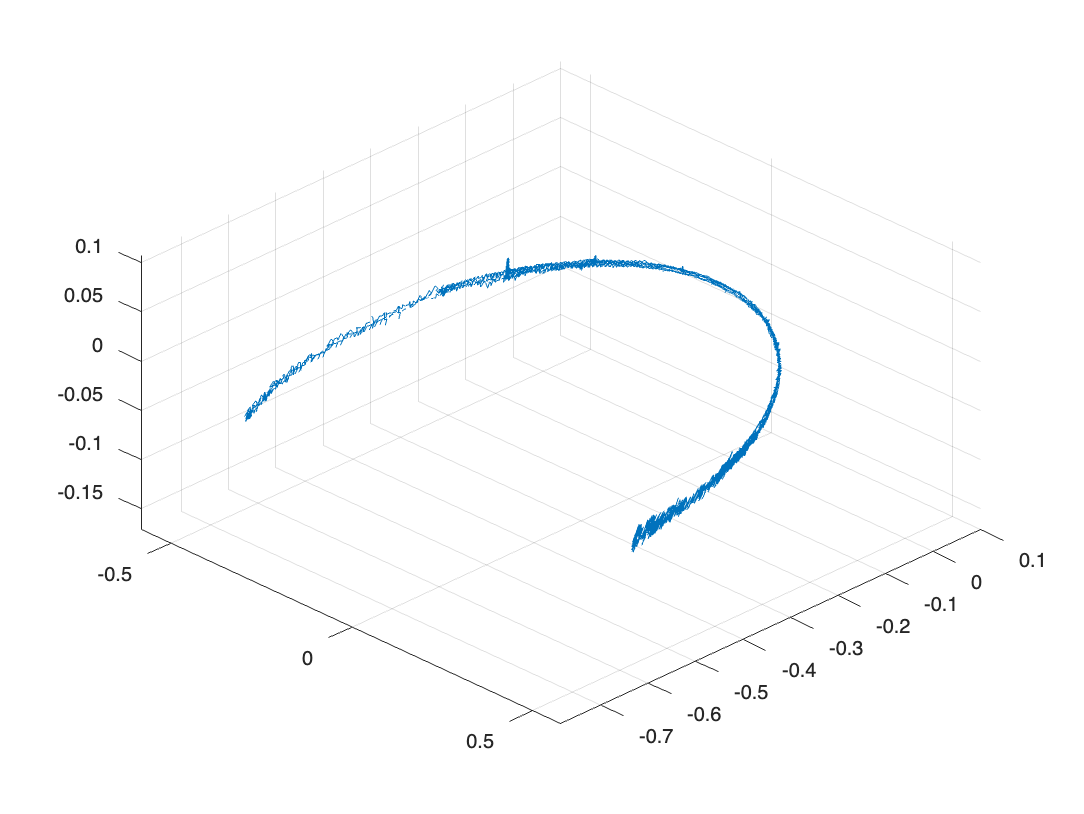


figure('Name','3D Trajectory'),clf,grid, hold on
plot3(GraphXk{1}(1:k),GraphXk{2}(1:k),GraphXk{3}(1:k))
axis([min(GraphXk{1}(1:k))-0.1 max(GraphXk{1}(1:k))+0.1 min(GraphXk{2}(1:k))-0.1 max(GraphXk{2}(1:k))+0.1 min(GraphXk{3}(1:k))-0.1 max(GraphXk{3}(1:k))+0.1])
view(45,45)

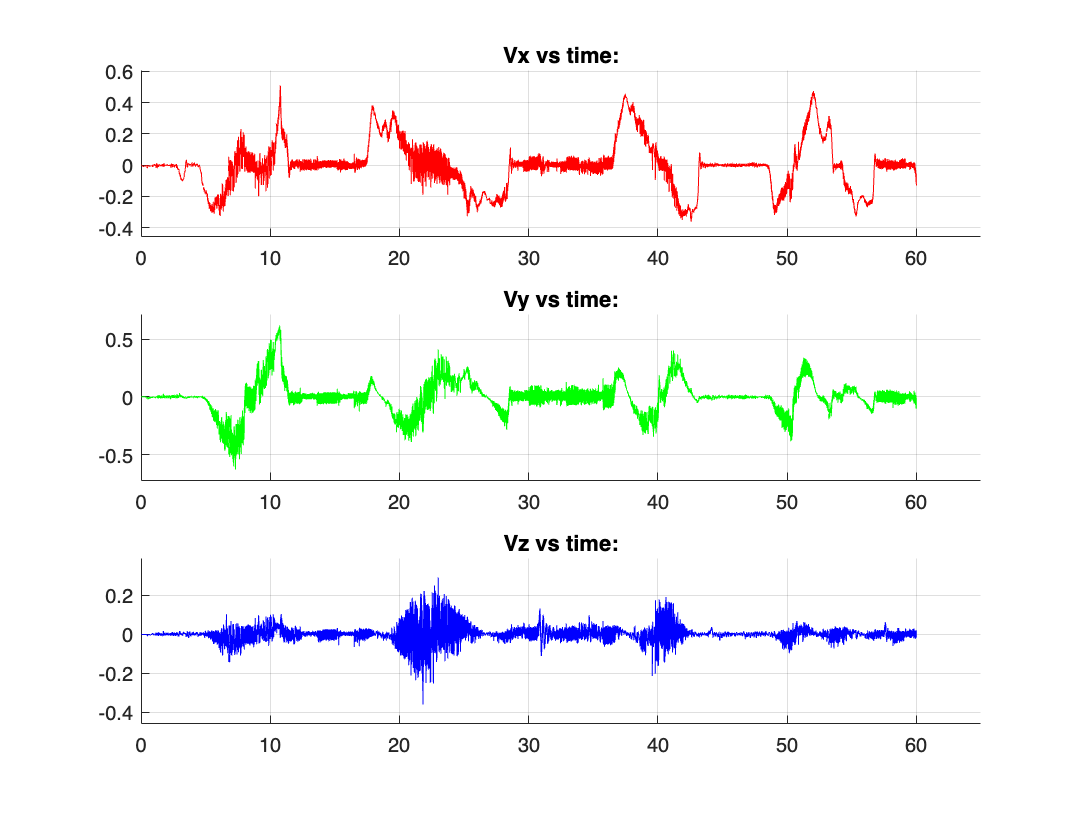


% Create a new figure
figure('Name', 'Velocity vs Time Plots'), clf

% Subplot for Vx vs time
subplot(3, 1, 1), grid, hold on
title('Vx vs time:')
plot(GraphXk{14}(1:k), GraphXk{4}(1:k), 'r-')
axis([0 GraphXk{14}(k)+5 min(GraphXk{4}(1:k))-0.1 max(GraphXk{4}(1:k))+0.1])

% Subplot for Vy vs time
subplot(3, 1, 2), grid, hold on
title('Vy vs time:')
plot(GraphXk{14}(1:k), GraphXk{5}(1:k), 'g-')
axis([0 GraphXk{14}(k)+5 min(GraphXk{5}(1:k))-0.1 max(GraphXk{5}(1:k))+0.1])

% Subplot for Vz vs time
subplot(3, 1, 3), grid, hold on
title('Vz vs time:')
plot(GraphXk{14}(1:k), GraphXk{6}(1:k), 'b-')
axis([0 GraphXk{14}(k)+5 min(GraphXk{6}(1:k))-0.1 max(GraphXk{6}(1:k))+0.1])

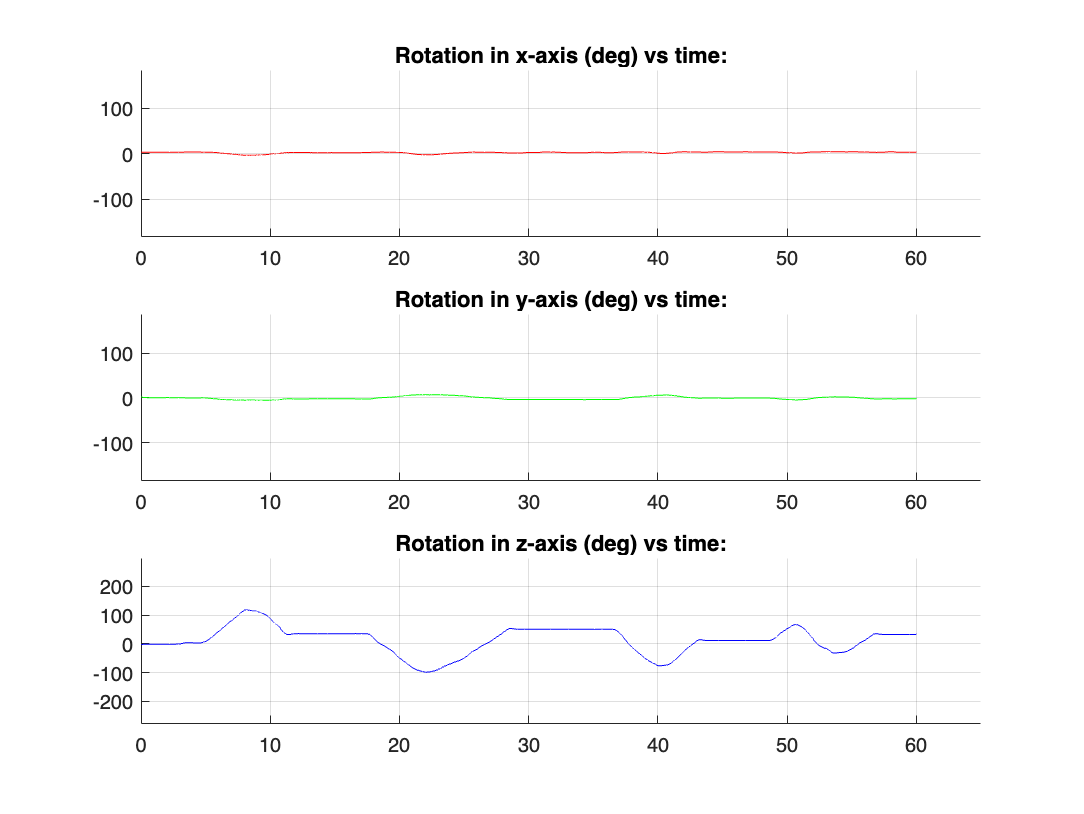



%Graphing orientation
eul_ZYXGraph = rad2deg(quat2eul([GraphXk{7}(1:k) GraphXk{8}(1:k) GraphXk{9}(1:k) GraphXk{10}(1:k)]));

% Create a new figure
figure('Name', 'Rotation vs Time Plots'), clf

% Subplot for rotation in x-axis vs time
subplot(3, 1, 1), grid, hold on
title('Rotation in x-axis (deg) vs time:')
plot(GraphXk{14}(1:k), eul_ZYXGraph(:,3), 'r-')
axis([0 GraphXk{14}(k)+5 min(eul_ZYXGraph(:,3))-180 max(eul_ZYXGraph(:,3))+180])

% Subplot for rotation in y-axis vs time
subplot(3, 1, 2), grid, hold on
title('Rotation in y-axis (deg) vs time:')
plot(GraphXk{14}(1:k), eul_ZYXGraph(:,2), 'g-')
axis([0 GraphXk{14}(k)+5 min(eul_ZYXGraph(:,2))-180 max(eul_ZYXGraph(:,2))+180])

% Subplot for rotation in z-axis vs time
subplot(3, 1, 3), grid, hold on
title('Rotation in z-axis (deg) vs time:')
plot(GraphXk{14}(1:k), eul_ZYXGraph(:,1), 'b-')
axis([0 GraphXk{14}(k)+5 min(eul_ZYXGraph(:,1))-180 max(eul_ZYXGraph(:,1))+180])


i=0

i = 0

k;
pos_record = zeros(i,1);
for p = 1:k
    if any(bDATA_Check{p})
        i = i+1;
        pos_record(i) = p;
    end   
end


pos_record_2cams = zeros(k,1);
count1=0;
count2=0;
count3=0;
count4=0;
count5=0;
count6=0;
openLoopCount=0;
for p = 1:k
    switch sum(bDATA_Check{p})
        case 1
            count1=count1+1;
        case 2
            count2=count2+1;
        case 3
            count3=count3+1;
        case 4
            count4=count4+1;
        case 5
            count5=count5+1;
        case 6
            count6=count6+1;
        otherwise
            openLoopCount=openLoopCount+1;
    end
end

count_data = [count1,count2,count3,count4,count5,count6]

count_data =         2171        2246         805          28           0           0


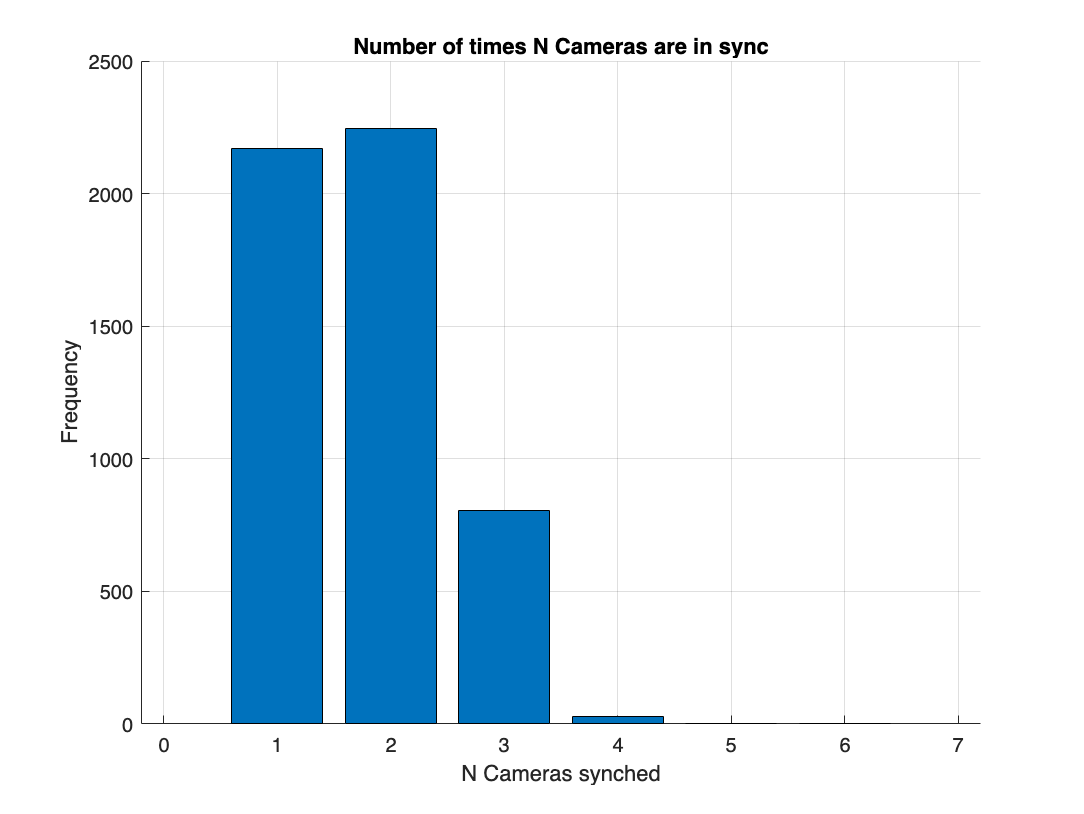

figure(10),clf,grid,hold on
bar(count_data);
title('Number of times N Cameras are in sync');
xlabel('N Cameras synched');
ylabel('Frequency');

disp(['Number of iterations: ',num2str(k)])

Number of iterations: 5743


disp(['Number of open loop iterations: ',num2str(openLoopCount)])

Number of open loop iterations: 493


disp(['Number of closed loop iteration: ',num2str(k-openLoopCount)])

Number of closed loop iteration: 5250


function error = computeReprojectionError(pose, worldPoints, imagePoints, cParams)
    % Decompose Pose Parameters
    rotationVector = pose(1:3);
    translationVector = pose(4:6);

    % Project World Points to Image Plane using estimated pose
    projectedPoints = world2img(worldPoints, rigidtform3d([eul2rotm(rotationVector) translationVector'; 0 0 0 1]), cParams.Intrinsics);

    % Compute Reprojection Error
    error = projectedPoints - imagePoints;
    error = error(:); % Reshape to a vector for lsqnonlin
end
%Optimise Extrinsics Function ^
%---------------------------------------------------------------------------------

%---------------------------------------------------------------------------------
% FUNDAMENTAL MATRIX FUNCTION
function F = FMat(cInt1,cInt2,camPose_1,camPose_2)
    %DRAWS LINE FROM 1 (U,V) ONTO 2: (therefore, 2 will have the epipolar
    %line from and CAM 1 will be master CAM).
    %______________________________
    K1 = cInt1.K; % Intrinsic matrix of Camera 1
    K2 = cInt2.K; % Intrinsic matrix of Camera 2
    R1 = camPose_1.R; % Rotation matrix of Camera 1 w.r.t world frame
    R2 = camPose_2.R; % Rotation matrix of Camera 2 w.r.t world frame
    t1 = camPose_1.Translation'; % Translation vector of Camera 1 w.r.t world frame
    t2 = camPose_2.Translation'; % Translation vector of Camera 2 w.r.t world frame
    % Compute the essential matrix
    R = R2' * R1; % Relative rotation between Camera 1 and Camera 2
    t = R2'*(t2 - t1);  % Relative translation between Camera 1 and Camera 2
    T_x = [0 -t(3) t(2); t(3) 0 -t(1); -t(2) t(1) 0]; % Skew-symmetric matrix of t
    E = T_x * R; % Essential matrix

    % Compute the fundamental matrix
    F = K2' \ E / K1; % Fundamental matrix
end
%---------------------------------------------------------------------------------
%PARSE DATA FUNCTION
function [timestamp, data, bUsable] = parseData(data)
    % Implement parsing logic here
    % Example: Split data based on delimiter ":"
    parts = split(data, ':');
    timestamp = str2double(parts{1}); % Assuming timestamp is numeric
    data = str2double(split(parts{2}(1:end-1),',')); % Assuming data is numeric
end

%---------------------------------------------------------------------------------
%SORT DATA FUNCTION
function UV = UV_prevSORT(UV_SCRAM, UV_Prev, bOpenMV)
    if bOpenMV
        UV_sorted = zeros(3, 2);
        for k = 1:3
            % Vectorized computation of distances
            distances = vecnorm(UV_Prev(k,:) - UV_SCRAM, 2, 2);
            [~, pos] = min(distances);
            UV_sorted(k, :) = UV_SCRAM(pos, :);
        end
        UV = UV_sorted;
    else
        UV = [];
    end
end
%---------------------------------------------------------------------------------
% H MATRIX FUNCTION
function H = HCreate(C1,Xkp,bOpenMV,f2b_1,f2b_2,f2b_3)
    if bOpenMV
        H = [C1(1,1)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,1)*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(1,2)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,2)*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(1,3)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,3)*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0, (C1(1,2)*(2*f2b_1(3) + 4*f2b_1(2)*Xkp(7) + 2*f2b_1(1)*Xkp(10)) + C1(1,3)*(4*f2b_1(3)*Xkp(7) + 2*f2b_1(2)*Xkp(8) - 2*f2b_1(1)*Xkp(9)) + C1(1,1)*(4*f2b_1(1)*Xkp(7) + 2*f2b_1(3)*Xkp(9) - 2*f2b_1(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_1(3) + 4*f2b_1(2)*Xkp(7) + 2*f2b_1(1)*Xkp(10)) + C1(3,3)*(4*f2b_1(3)*Xkp(7) + 2*f2b_1(2)*Xkp(8) - 2*f2b_1(1)*Xkp(9)) + C1(3,1)*(4*f2b_1(1)*Xkp(7) + 2*f2b_1(3)*Xkp(9) - 2*f2b_1(2)*Xkp(10)))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(1,3)*(2*f2b_1(2)*Xkp(7) + 2*f2b_1(1)*Xkp(10)) + C1(1,1)*(4*f2b_1(1)*Xkp(8) + 2*f2b_1(2)*Xkp(9) + 2*f2b_1(3)*Xkp(10)) + 2*C1(1,2)*f2b_1(1)*Xkp(9))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,3)*(2*f2b_1(2)*Xkp(7) + 2*f2b_1(1)*Xkp(10)) + C1(3,1)*(4*f2b_1(1)*Xkp(8) + 2*f2b_1(2)*Xkp(9) + 2*f2b_1(3)*Xkp(10)) + 2*C1(3,2)*f2b_1(1)*Xkp(9))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(1,2)*(2*f2b_1(1)*Xkp(8) + 4*f2b_1(2)*Xkp(9) + f2b_1(3)*(2*Xkp(10) + 2)) + C1(1,1)*(2*f2b_1(3)*Xkp(7) + 2*f2b_1(2)*Xkp(8)) - C1(1,3)*(2*f2b_1(1)*Xkp(7) - 2*f2b_1(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_1(1)*Xkp(8) + 4*f2b_1(2)*Xkp(9) + f2b_1(3)*(2*Xkp(10) + 2)) + C1(3,1)*(2*f2b_1(3)*Xkp(7) + 2*f2b_1(2)*Xkp(8)) - C1(3,3)*(2*f2b_1(1)*Xkp(7) - 2*f2b_1(2)*Xkp(10)))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(1,2)*(2*f2b_1(1)*Xkp(7) + 2*f2b_1(3)*Xkp(9)) - C1(1,1)*(2*f2b_1(2)*Xkp(7) - 2*f2b_1(3)*Xkp(8)) + C1(1,3)*(2*f2b_1(1)*Xkp(8) + 2*f2b_1(2)*Xkp(9) + 4*f2b_1(3)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_1(1)*Xkp(7) + 2*f2b_1(3)*Xkp(9)) - C1(3,1)*(2*f2b_1(2)*Xkp(7) - 2*f2b_1(3)*Xkp(8)) + C1(3,3)*(2*f2b_1(1)*Xkp(8) + 2*f2b_1(2)*Xkp(9) + 4*f2b_1(3)*Xkp(10)))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0; 
             C1(2,1)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,1)*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(2,2)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,2)*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(2,3)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,3)*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0, (C1(2,2)*(2*f2b_1(3) + 4*f2b_1(2)*Xkp(7) + 2*f2b_1(1)*Xkp(10)) + C1(2,3)*(4*f2b_1(3)*Xkp(7) + 2*f2b_1(2)*Xkp(8) - 2*f2b_1(1)*Xkp(9)) + C1(2,1)*(4*f2b_1(1)*Xkp(7) + 2*f2b_1(3)*Xkp(9) - 2*f2b_1(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_1(3) + 4*f2b_1(2)*Xkp(7) + 2*f2b_1(1)*Xkp(10)) + C1(3,3)*(4*f2b_1(3)*Xkp(7) + 2*f2b_1(2)*Xkp(8) - 2*f2b_1(1)*Xkp(9)) + C1(3,1)*(4*f2b_1(1)*Xkp(7) + 2*f2b_1(3)*Xkp(9) - 2*f2b_1(2)*Xkp(10)))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(2,3)*(2*f2b_1(2)*Xkp(7) + 2*f2b_1(1)*Xkp(10)) + C1(2,1)*(4*f2b_1(1)*Xkp(8) + 2*f2b_1(2)*Xkp(9) + 2*f2b_1(3)*Xkp(10)) + 2*C1(2,2)*f2b_1(1)*Xkp(9))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,3)*(2*f2b_1(2)*Xkp(7) + 2*f2b_1(1)*Xkp(10)) + C1(3,1)*(4*f2b_1(1)*Xkp(8) + 2*f2b_1(2)*Xkp(9) + 2*f2b_1(3)*Xkp(10)) + 2*C1(3,2)*f2b_1(1)*Xkp(9))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(2,2)*(2*f2b_1(1)*Xkp(8) + 4*f2b_1(2)*Xkp(9) + f2b_1(3)*(2*Xkp(10) + 2)) + C1(2,1)*(2*f2b_1(3)*Xkp(7) + 2*f2b_1(2)*Xkp(8)) - C1(2,3)*(2*f2b_1(1)*Xkp(7) - 2*f2b_1(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_1(1)*Xkp(8) + 4*f2b_1(2)*Xkp(9) + f2b_1(3)*(2*Xkp(10) + 2)) + C1(3,1)*(2*f2b_1(3)*Xkp(7) + 2*f2b_1(2)*Xkp(8)) - C1(3,3)*(2*f2b_1(1)*Xkp(7) - 2*f2b_1(2)*Xkp(10)))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(2,2)*(2*f2b_1(1)*Xkp(7) + 2*f2b_1(3)*Xkp(9)) - C1(2,1)*(2*f2b_1(2)*Xkp(7) - 2*f2b_1(3)*Xkp(8)) + C1(2,3)*(2*f2b_1(1)*Xkp(8) + 2*f2b_1(2)*Xkp(9) + 4*f2b_1(3)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_1(1)*Xkp(7) + 2*f2b_1(3)*Xkp(9)) - C1(3,1)*(2*f2b_1(2)*Xkp(7) - 2*f2b_1(3)*Xkp(8)) + C1(3,3)*(2*f2b_1(1)*Xkp(8) + 2*f2b_1(2)*Xkp(9) + 4*f2b_1(3)*Xkp(10)))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0;
             C1(1,1)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,1)*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(1,2)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,2)*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(1,3)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,3)*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0, (C1(1,2)*(2*f2b_2(3) + 4*f2b_2(2)*Xkp(7) + 2*f2b_2(1)*Xkp(10)) + C1(1,3)*(4*f2b_2(3)*Xkp(7) + 2*f2b_2(2)*Xkp(8) - 2*f2b_2(1)*Xkp(9)) + C1(1,1)*(4*f2b_2(1)*Xkp(7) + 2*f2b_2(3)*Xkp(9) - 2*f2b_2(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_2(3) + 4*f2b_2(2)*Xkp(7) + 2*f2b_2(1)*Xkp(10)) + C1(3,3)*(4*f2b_2(3)*Xkp(7) + 2*f2b_2(2)*Xkp(8) - 2*f2b_2(1)*Xkp(9)) + C1(3,1)*(4*f2b_2(1)*Xkp(7) + 2*f2b_2(3)*Xkp(9) - 2*f2b_2(2)*Xkp(10)))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(1,3)*(2*f2b_2(2)*Xkp(7) + 2*f2b_2(1)*Xkp(10)) + C1(1,1)*(4*f2b_2(1)*Xkp(8) + 2*f2b_2(2)*Xkp(9) + 2*f2b_2(3)*Xkp(10)) + 2*C1(1,2)*f2b_2(1)*Xkp(9))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,3)*(2*f2b_2(2)*Xkp(7) + 2*f2b_2(1)*Xkp(10)) + C1(3,1)*(4*f2b_2(1)*Xkp(8) + 2*f2b_2(2)*Xkp(9) + 2*f2b_2(3)*Xkp(10)) + 2*C1(3,2)*f2b_2(1)*Xkp(9))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(1,2)*(2*f2b_2(1)*Xkp(8) + 4*f2b_2(2)*Xkp(9) + f2b_2(3)*(2*Xkp(10) + 2)) + C1(1,1)*(2*f2b_2(3)*Xkp(7) + 2*f2b_2(2)*Xkp(8)) - C1(1,3)*(2*f2b_2(1)*Xkp(7) - 2*f2b_2(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_2(1)*Xkp(8) + 4*f2b_2(2)*Xkp(9) + f2b_2(3)*(2*Xkp(10) + 2)) + C1(3,1)*(2*f2b_2(3)*Xkp(7) + 2*f2b_2(2)*Xkp(8)) - C1(3,3)*(2*f2b_2(1)*Xkp(7) - 2*f2b_2(2)*Xkp(10)))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(1,2)*(2*f2b_2(1)*Xkp(7) + 2*f2b_2(3)*Xkp(9)) - C1(1,1)*(2*f2b_2(2)*Xkp(7) - 2*f2b_2(3)*Xkp(8)) + C1(1,3)*(2*f2b_2(1)*Xkp(8) + 2*f2b_2(2)*Xkp(9) + 4*f2b_2(3)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_2(1)*Xkp(7) + 2*f2b_2(3)*Xkp(9)) - C1(3,1)*(2*f2b_2(2)*Xkp(7) - 2*f2b_2(3)*Xkp(8)) + C1(3,3)*(2*f2b_2(1)*Xkp(8) + 2*f2b_2(2)*Xkp(9) + 4*f2b_2(3)*Xkp(10)))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0; 
             C1(2,1)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,1)*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(2,2)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,2)*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(2,3)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,3)*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0, (C1(2,2)*(2*f2b_2(3) + 4*f2b_2(2)*Xkp(7) + 2*f2b_2(1)*Xkp(10)) + C1(2,3)*(4*f2b_2(3)*Xkp(7) + 2*f2b_2(2)*Xkp(8) - 2*f2b_2(1)*Xkp(9)) + C1(2,1)*(4*f2b_2(1)*Xkp(7) + 2*f2b_2(3)*Xkp(9) - 2*f2b_2(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_2(3) + 4*f2b_2(2)*Xkp(7) + 2*f2b_2(1)*Xkp(10)) + C1(3,3)*(4*f2b_2(3)*Xkp(7) + 2*f2b_2(2)*Xkp(8) - 2*f2b_2(1)*Xkp(9)) + C1(3,1)*(4*f2b_2(1)*Xkp(7) + 2*f2b_2(3)*Xkp(9) - 2*f2b_2(2)*Xkp(10)))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(2,3)*(2*f2b_2(2)*Xkp(7) + 2*f2b_2(1)*Xkp(10)) + C1(2,1)*(4*f2b_2(1)*Xkp(8) + 2*f2b_2(2)*Xkp(9) + 2*f2b_2(3)*Xkp(10)) + 2*C1(2,2)*f2b_2(1)*Xkp(9))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,3)*(2*f2b_2(2)*Xkp(7) + 2*f2b_2(1)*Xkp(10)) + C1(3,1)*(4*f2b_2(1)*Xkp(8) + 2*f2b_2(2)*Xkp(9) + 2*f2b_2(3)*Xkp(10)) + 2*C1(3,2)*f2b_2(1)*Xkp(9))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(2,2)*(2*f2b_2(1)*Xkp(8) + 4*f2b_2(2)*Xkp(9) + f2b_2(3)*(2*Xkp(10) + 2)) + C1(2,1)*(2*f2b_2(3)*Xkp(7) + 2*f2b_2(2)*Xkp(8)) - C1(2,3)*(2*f2b_2(1)*Xkp(7) - 2*f2b_2(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_2(1)*Xkp(8) + 4*f2b_2(2)*Xkp(9) + f2b_2(3)*(2*Xkp(10) + 2)) + C1(3,1)*(2*f2b_2(3)*Xkp(7) + 2*f2b_2(2)*Xkp(8)) - C1(3,3)*(2*f2b_2(1)*Xkp(7) - 2*f2b_2(2)*Xkp(10)))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(2,2)*(2*f2b_2(1)*Xkp(7) + 2*f2b_2(3)*Xkp(9)) - C1(2,1)*(2*f2b_2(2)*Xkp(7) - 2*f2b_2(3)*Xkp(8)) + C1(2,3)*(2*f2b_2(1)*Xkp(8) + 2*f2b_2(2)*Xkp(9) + 4*f2b_2(3)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_2(1)*Xkp(7) + 2*f2b_2(3)*Xkp(9)) - C1(3,1)*(2*f2b_2(2)*Xkp(7) - 2*f2b_2(3)*Xkp(8)) + C1(3,3)*(2*f2b_2(1)*Xkp(8) + 2*f2b_2(2)*Xkp(9) + 4*f2b_2(3)*Xkp(10)))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0; 
             C1(1,1)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,1)*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(1,2)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,2)*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(1,3)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,3)*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0, (C1(1,2)*(2*f2b_3(3) + 4*f2b_3(2)*Xkp(7) + 2*f2b_3(1)*Xkp(10)) + C1(1,3)*(4*f2b_3(3)*Xkp(7) + 2*f2b_3(2)*Xkp(8) - 2*f2b_3(1)*Xkp(9)) + C1(1,1)*(4*f2b_3(1)*Xkp(7) + 2*f2b_3(3)*Xkp(9) - 2*f2b_3(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_3(3) + 4*f2b_3(2)*Xkp(7) + 2*f2b_3(1)*Xkp(10)) + C1(3,3)*(4*f2b_3(3)*Xkp(7) + 2*f2b_3(2)*Xkp(8) - 2*f2b_3(1)*Xkp(9)) + C1(3,1)*(4*f2b_3(1)*Xkp(7) + 2*f2b_3(3)*Xkp(9) - 2*f2b_3(2)*Xkp(10)))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(1,3)*(2*f2b_3(2)*Xkp(7) + 2*f2b_3(1)*Xkp(10)) + C1(1,1)*(4*f2b_3(1)*Xkp(8) + 2*f2b_3(2)*Xkp(9) + 2*f2b_3(3)*Xkp(10)) + 2*C1(1,2)*f2b_3(1)*Xkp(9))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,3)*(2*f2b_3(2)*Xkp(7) + 2*f2b_3(1)*Xkp(10)) + C1(3,1)*(4*f2b_3(1)*Xkp(8) + 2*f2b_3(2)*Xkp(9) + 2*f2b_3(3)*Xkp(10)) + 2*C1(3,2)*f2b_3(1)*Xkp(9))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(1,2)*(2*f2b_3(1)*Xkp(8) + 4*f2b_3(2)*Xkp(9) + f2b_3(3)*(2*Xkp(10) + 2)) + C1(1,1)*(2*f2b_3(3)*Xkp(7) + 2*f2b_3(2)*Xkp(8)) - C1(1,3)*(2*f2b_3(1)*Xkp(7) - 2*f2b_3(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_3(1)*Xkp(8) + 4*f2b_3(2)*Xkp(9) + f2b_3(3)*(2*Xkp(10) + 2)) + C1(3,1)*(2*f2b_3(3)*Xkp(7) + 2*f2b_3(2)*Xkp(8)) - C1(3,3)*(2*f2b_3(1)*Xkp(7) - 2*f2b_3(2)*Xkp(10)))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(1,2)*(2*f2b_3(1)*Xkp(7) + 2*f2b_3(3)*Xkp(9)) - C1(1,1)*(2*f2b_3(2)*Xkp(7) - 2*f2b_3(3)*Xkp(8)) + C1(1,3)*(2*f2b_3(1)*Xkp(8) + 2*f2b_3(2)*Xkp(9) + 4*f2b_3(3)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_3(1)*Xkp(7) + 2*f2b_3(3)*Xkp(9)) - C1(3,1)*(2*f2b_3(2)*Xkp(7) - 2*f2b_3(3)*Xkp(8)) + C1(3,3)*(2*f2b_3(1)*Xkp(8) + 2*f2b_3(2)*Xkp(9) + 4*f2b_3(3)*Xkp(10)))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0; 
             C1(2,1)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,1)*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(2,2)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,2)*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(2,3)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,3)*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0, (C1(2,2)*(2*f2b_3(3) + 4*f2b_3(2)*Xkp(7) + 2*f2b_3(1)*Xkp(10)) + C1(2,3)*(4*f2b_3(3)*Xkp(7) + 2*f2b_3(2)*Xkp(8) - 2*f2b_3(1)*Xkp(9)) + C1(2,1)*(4*f2b_3(1)*Xkp(7) + 2*f2b_3(3)*Xkp(9) - 2*f2b_3(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_3(3) + 4*f2b_3(2)*Xkp(7) + 2*f2b_3(1)*Xkp(10)) + C1(3,3)*(4*f2b_3(3)*Xkp(7) + 2*f2b_3(2)*Xkp(8) - 2*f2b_3(1)*Xkp(9)) + C1(3,1)*(4*f2b_3(1)*Xkp(7) + 2*f2b_3(3)*Xkp(9) - 2*f2b_3(2)*Xkp(10)))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(2,3)*(2*f2b_3(2)*Xkp(7) + 2*f2b_3(1)*Xkp(10)) + C1(2,1)*(4*f2b_3(1)*Xkp(8) + 2*f2b_3(2)*Xkp(9) + 2*f2b_3(3)*Xkp(10)) + 2*C1(2,2)*f2b_3(1)*Xkp(9))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,3)*(2*f2b_3(2)*Xkp(7) + 2*f2b_3(1)*Xkp(10)) + C1(3,1)*(4*f2b_3(1)*Xkp(8) + 2*f2b_3(2)*Xkp(9) + 2*f2b_3(3)*Xkp(10)) + 2*C1(3,2)*f2b_3(1)*Xkp(9))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(2,2)*(2*f2b_3(1)*Xkp(8) + 4*f2b_3(2)*Xkp(9) + f2b_3(3)*(2*Xkp(10) + 2)) + C1(2,1)*(2*f2b_3(3)*Xkp(7) + 2*f2b_3(2)*Xkp(8)) - C1(2,3)*(2*f2b_3(1)*Xkp(7) - 2*f2b_3(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_3(1)*Xkp(8) + 4*f2b_3(2)*Xkp(9) + f2b_3(3)*(2*Xkp(10) + 2)) + C1(3,1)*(2*f2b_3(3)*Xkp(7) + 2*f2b_3(2)*Xkp(8)) - C1(3,3)*(2*f2b_3(1)*Xkp(7) - 2*f2b_3(2)*Xkp(10)))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(2,2)*(2*f2b_3(1)*Xkp(7) + 2*f2b_3(3)*Xkp(9)) - C1(2,1)*(2*f2b_3(2)*Xkp(7) - 2*f2b_3(3)*Xkp(8)) + C1(2,3)*(2*f2b_3(1)*Xkp(8) + 2*f2b_3(2)*Xkp(9) + 4*f2b_3(3)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_3(1)*Xkp(7) + 2*f2b_3(3)*Xkp(9)) - C1(3,1)*(2*f2b_3(2)*Xkp(7) - 2*f2b_3(3)*Xkp(8)) + C1(3,3)*(2*f2b_3(1)*Xkp(8) + 2*f2b_3(2)*Xkp(9) + 4*f2b_3(3)*Xkp(10)))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0]; 
    else
        H = [];
    end
end
%---------------------------------------------------------------------------------
% HXkp Function
function [HXkp,HXkp_32] = createHXkp(Xkp,R_QUAT,f2b_1,f2b_2,f2b_3, extrinsics, cameraParams, isOpenMV)
    if isOpenMV
        HXkp_32 = world2img([(Xkp(1:3)+R_QUAT*f2b_1)';(Xkp(1:3)+R_QUAT*f2b_2)';(Xkp(1:3)+R_QUAT*f2b_3)'],rigidtform3d(extrinsics),cameraParams);
        HXkp_23 = HXkp_32';
        HXkp = HXkp_23(:);
    else 
        HXkp_32 = world2img([(Xkp(1:3)+R_QUAT*f2b_1)';(Xkp(1:3)+R_QUAT*f2b_2)';(Xkp(1:3)+R_QUAT*f2b_3)'],rigidtform3d(extrinsics),cameraParams);
        HXkp = [];
    end
end
%---------------------------------------------------------------------------------
% R Function
function R = createR(bNum)
    % Create the identity matrix
    R = eye(6 * bNum);
end
%---------------------------------------------------------------------------------
% Yk Function
function Yk = createYk(UV_1,UV_2,UV_3,UV_4,UV_5,UV_6,b1,b2,b3,b4,b5,b6)
    if b1
        Yk_UV1 = [UV_1(1,:)';UV_1(2,:)';UV_1(3,:)'];
    else
        Yk_UV1 = [];
    end
    if b2
        Yk_UV2 = [UV_2(1,:)';UV_2(2,:)';UV_2(3,:)'];
    else
        Yk_UV2 = [];
    end
    if b3
        Yk_UV3 = [UV_3(1,:)';UV_3(2,:)';UV_3(3,:)'];
    else
        Yk_UV3 = [];
    end
    if b4
        Yk_UV4 = [UV_4(1,:)';UV_4(2,:)';UV_4(3,:)'];
    else
        Yk_UV4 = [];
    end
    if b5
        Yk_UV5 = [UV_5(1,:)';UV_5(2,:)';UV_5(3,:)'];
    else
        Yk_UV5 = [];
    end
    if b6
        Yk_UV6 = [UV_6(1,:)';UV_6(2,:)';UV_6(3,:)'];
    else
        Yk_UV6 = [];
    end
    Yk = [Yk_UV1;Yk_UV2;Yk_UV3;Yk_UV4;Yk_UV5;Yk_UV6];
end
